# Laboratorio: optimización sin restricciones

**Autor: **PhD Lucía Royo

**Objetivos**

La idea de este Laboratorio es estudiar un caso de optimización sin restricciones multivariables. Justamente, con la implementación del método del gradiente, se espera aproximar una curva que verifica ciertas condiciones. Esta actividad busca fomentar la exploración, comprensión e implementación del método del descenso del gradiente en un problema exigente desde el punto de vista computacional. Así, se espera que se logre determinar la conexión de este método con lo estudiado para la Actividad 1.

**Problema**

El objetivo para esta entrega consiste en encontrar la curva que une los puntos $\left(0,\ 1\right)$ y $\left(1,\ 1\right)$, de forma que se minimice el área de la superficie de revolución alrededor del eje. Para ello, se quiere minimizar la integral:


$$I{\left(u\right)}=\int_0^1 u{\left(x\right)}\sqrt{1+{{\left[u^{\prime } {\left(x\right)}\right]}}^2 }\ dx$$


Sujeta a las condiciones:  $u{\left(0\right)}=1=u\left(1\right)$                   

En realidad, el área deseada es $2\pi I\left(u\right)$. Sin embargo, el factor $2\pi$ no es relevante y se puede normalizar para facilitar los cálculos.

**Metodología**

Para resolver este problema, realizaremos una discretización del intervalo $\left\lbrack 0,\ 1\right\rbrack$, de forma que tomaremos   intervalos de la forma: ${\left[\frac{j}{n},\ \frac{j+1}{n}\right]}$, para  $0\le j\le n-1$.

Recordemos que si consideramos una función $f\left(x\right)$, la integración por trapecios nos da la fórmula:

 
$$\int_0^1 f{\left(x\right)}dx\approx \sum_{j=0}^{n-1} \frac{f{\left(x_j \right)}+f\left(x_{j+1} \right)}{2}\cdot \frac{1}{n}=\sum_{j=0}^{n-1} T_j \left(f\left(x\right)\right)$$


En nuestro caso, tendremos $f\left(x\right)\ =u{\left(x\right)}\sqrt{1+{{\left[u^{\prime } {\left(x\right)}\right]}}^2 }$ y llamaremos $u_j \ =\ u\left(x_j \right)$. Como estamos aproximando   por una poligonal, podemos considerar que:


$$u^{\prime } {\left(x_j \right)}\approx \frac{u{\left(x_{j+1} \right)}-u{\left(x_j \right)}}{\frac{1}{n}}=n\left\lbrack u{\left(x_{j+1} \right)}-u\left(x_j \right)\right\rbrack$$


Es decir, aproximamos la derivada por la derecha para el punto inicial y por la izquierda en el punto final. Por lo que la aproximación de la integral será:

Así pues, se obtiene la siguiente función, que podemos optimizar usando el método del gradiente:

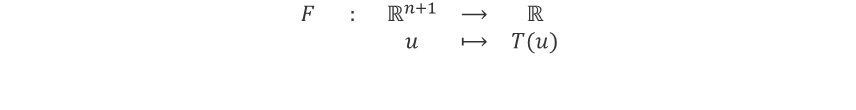

**Implementación**

Para la implementación, se deben seguir los siguientes pasos:

- Calcular el gradiente de                               

- Calcular la curva óptima para los distintos valores de $n$, teniendo en cuenta que:


$$T_j {\left(u\right)}=\frac{1}{2\left(n+1\right)}\cdot {\left(u_{j+1} +u_j \right)}\sqrt{1+{\left(n+1\right)}^2 {{\left(u_{j+1} -u_j \right)}}^2 }$$


- El gradiente está formado por:


$$\nabla F{\left(u_0 ,u_1 ,\ldots,\ u_n \right)}={{\left[g_0 ,g_1 ,\ldots,g_n \right]}}^T$$


Donde:

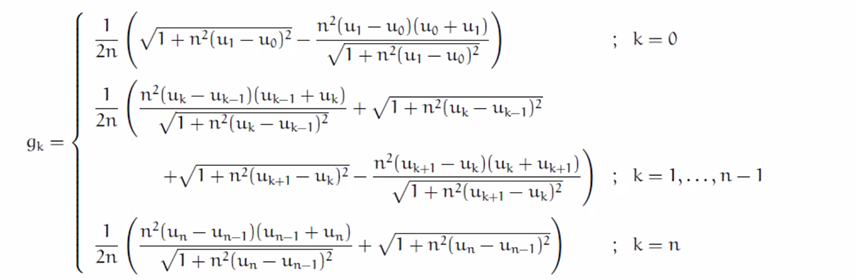

**Pautas de elaboración**

- Deberás determinar cuál es la curva tal que, al considerar su sólido de revolución, el área de superficie es mínima. Para hacerlo, ten en cuenta que la incógnita del problema es una función (es necesario discretizarla, como se explica en los apartados anteriores). Al discretizar, el problema se convierte en uno multidimensional de dimensión alta.

- El informe debe entregarse en formato PDF, donde sea posible discriminar cada uno de los aspectos listados en la tabla anexa para la rúbrica.

- Deberás entregar un fichero en `Matlab` que permita verificar los resultados. Es importante destacar que ese fichero debe correr directamente sin señalar error alguno.

**Calculamos optimización utilizando el método de paso fijo**

clear all;
format longg;

%% Configuración de barridos
n_values = [5, 10, 15, 20, 25, 50]; % Valores de n
t_values = [0.001, 0.01,0.15]; % Valores de t_k

% Para guardar los resultados de cada barrido
resultados = struct();
figure_count = 1; % Contador de figuras para evitar sobreescritura

% Crear carpeta para guardar resultados
output_folder = 'resultados_tvariable';
if ~exist(output_folder, 'dir')
    mkdir(output_folder);
end

%% Barrido de parámetros
for n_idx = 1:length(n_values)
    for t_idx = 1:length(t_values)
        % Definir parámetros actuales
        n = n_values(n_idx);
        t_k = t_values(t_idx);

        %% Paso 1: Inicializar el algoritmo
        x0 = 0;
        xn = 1;
        Xinit = linspace(x0, xn, n+1); % Iniciamos en el origen
        Uinit = ones(1, n+1); % Iniciamos en el origen
        u0 = 1;
        un = 1;

        delta = 1e-5; % Tolerancia para la convergencia
        max_iter = 1000; % Número máximo de iteraciones
        iter = 0;
        epsilon = delta / 10;  % Distancia entre los puntos (epsilon < delta)

        % Inicializar errores
        error_1 = delta + 1;
        error_2 = delta + 1;
        x_k = Uinit;
        x_hist = x_k';

        % Inicializar tabla para guardar los resultados por iteración
        tabla_iteraciones = [];
        % superior_0 = true; % Condición para evitar valores menores que 0

        % Preparar grabación de video
        video_filename = fullfile(output_folder, sprintf('gradiente_n%d_t%.3f.mp4', n, t_k));
        video_writer = VideoWriter(video_filename, 'MPEG-4');
        open(video_writer);

        %% Implementación del Método del Gradiente Descendente
        tic
        while (error_1 > delta || error_2 > delta) && iter < max_iter
            iter = iter + 1;

            %% Paso 2: Calcular el gradiente en el punto actual
            gradiente = compute_gk(x_k);
            
            %% Calculamos las Tj de cada x_k
            % Tj(iter, :) = calcularT(x_k);
            % T_suma(iter) = compute_T_and_sum(x_k);

            ft = @(t) compute_T_and_sum(x_k - t .* gradiente);        % Definir la función unidimensional en la dirección del gradiente
            t_k = busqueda_dicotomica(ft, 0, 1, delta,max_iter,epsilon); % Búsqueda dicotómica para encontrar t_k óptimo

            %% Paso 3: Actualizar el punto usando el gradiente descendente
            x_k_plus_1 = x_k - t_k .* gradiente;
            x_k_plus_1(1) = 1; x_k_plus_1(n+1) = 1; % exijo las condiciones de contorno!!!

            %% Calcular los errores
            error_1 = norm(x_k_plus_1 - x_k);
            error_2 = norm(compute_gk(x_k_plus_1));

            %% Guardar resultados en cada iteración
            tabla_iteraciones = [tabla_iteraciones; iter, x_k, compute_T_and_sum(x_k), error_1, error_2];

            % Actualizar x_k y guardar el historial
            x_k = x_k_plus_1;
            x_hist = [x_hist; x_k'];


            % Gráfico 2D de X vs U (Figura 1)
            figure(figure_count); % Crear una figura nueva para evitar sobreescritura
            
            x_values = linspace(x0, xn, n+1);
            
            % Graficar puntos discretos
            plot(x_values, x_k, '-o', 'LineWidth', 1.5)
            grid on;
            title(['Iteración: ', num2str(iter), ' (n=', num2str(n), ', t_k=', num2str(t_k), ')']);
            xlabel('Intervalo X');
            ylabel('Valores de U');
            xlim([x0 xn]);
            ylim([min(x_k) - 0.1, max(x_k) + 0.1]); % Ajustar los límites de Y dinámicamente
            pause(0.1); % Pausa para animación

            % Guardar frame en el video
            frame = getframe(gcf);
            writeVideo(video_writer, frame);
            disp(['t',num2str(t_idx),'n',num2str(n_idx),'Iteracion:',num2str(iter)])
        end

        %% Calcular el área debajo de la curva
        area_debajo_curva = trapz(x_values, x_k);
        disp(['Área debajo de la curva (n=', num2str(n), ', t_k=', num2str(t_k), '): ', num2str(area_debajo_curva)]);

        %% Gráfico final de X vs U (Figura 2)
        figure_count = figure_count + 1; % Incrementar el número de figura
        figure(figure_count);
        plot(x_values, x_k, '-o', 'LineWidth', 1.5);
        grid on;
        title(['Iteración: ', num2str(iter), ' (n=', num2str(n), ', t_k=', num2str(t_k), ')']);
        xlabel('Intervalo X');
        ylabel('Valores de U');
        xlim([x0 xn]);
        ylim([min(x_k) - 0.1, max(x_k) + 0.1]); % Ajustar los límites de Y dinámicamente

        % Guardar la figura
        saveas(gcf, fullfile(output_folder, sprintf('final_n%d_t%.3f.pdf', n, t_k)));

        %% Sólido de revolución (Figura 3)
        figure_count = figure_count + 1; % Incrementar el número de figura
        theta = linspace(0, 2*pi, 100); % Ángulo de revolución
        [X, T] = meshgrid(x_values, theta);
        U = x_k; % Usar los valores originales de U sin interpolación
        R = repmat(U, size(T, 1), 1); % Repetir U para todas las rotaciones
        Y = R .* cos(T); % Coordenada Y
        Z = R .* sin(T); % Coordenada Z

        figure(figure_count);
        surf(X, Y, Z, 'EdgeColor', 'none'); % Gráfico 3D
        colormap('jet');
        shading interp;
        title(['Sólido de revolución (n=', num2str(n), ', t_k=', num2str(t_k), ')']);
        xlabel('X');
        ylabel('Y');
        zlabel('Z');
        axis equal;
        grid on;
        view([16.60 45.82]);

        % Guardar la figura
        saveas(gcf, fullfile(output_folder, sprintf('solid_n%d_t%.3f.pdf', n, t_k)));

        % Cerrar video
        close(video_writer);

        %% Guardar los resultados del barrido
        x_opt = x_k;
        f_opt = compute_T_and_sum(x_k);
        elapsedTime = toc;

        resultados.(['n_' num2str(n) '_t_' strrep(num2str(t_k), '.', '_')]) = struct(...
            'x_opt', x_opt, ...
            'f_opt', f_opt, ...
            'area', area_debajo_curva, ...
            'iter', iter, ...
            'elapsedTime', elapsedTime, ...
            'tabla_iteraciones', tabla_iteraciones ...
        );

        %% Mostrar resultados parciales
        disp(['Resultados para n = ' num2str(n) ', t_k = ' num2str(t_k)]);
        disp('Punto óptimo (x):');
        disp(x_opt);
        disp('Valor óptimo de f(x):');
        disp(f_opt);
        disp('Área debajo de la curva:');
        disp(area_debajo_curva);
        disp('Número de iteraciones:');
        disp(iter);
        disp('Tiempo en segundos:');
        disp(elapsedTime);
        figure_count = figure_count + 1; % Incrementar el contador de figuras
    end
    clear T_suma;
    clear Tj;
end

Valor óptimo de f(x): 0.742760


t1n1Iteracion:1


Valor óptimo de f(x): 0.760322


t1n1Iteracion:2


Valor óptimo de f(x): 0.735536


t1n1Iteracion:3


Valor óptimo de f(x): 0.766997


t1n1Iteracion:4


Valor óptimo de f(x): 0.750817


t1n1Iteracion:5


Valor óptimo de f(x): 0.776659


t1n1Iteracion:6


Valor óptimo de f(x): 0.759156


t1n1Iteracion:7


Valor óptimo de f(x): 0.781647


t1n1Iteracion:8


Valor óptimo de f(x): 0.763526


t1n1Iteracion:9


Valor óptimo de f(x): 0.784021


t1n1Iteracion:10


Valor óptimo de f(x): 0.765525


t1n1Iteracion:11


Valor óptimo de f(x): 0.785126


t1n1Iteracion:12


Valor óptimo de f(x): 0.766435


t1n1Iteracion:13


Valor óptimo de f(x): 0.785594


t1n1Iteracion:14


Valor óptimo de f(x): 0.766800


t1n1Iteracion:15


Valor óptimo de f(x): 0.785796


t1n1Iteracion:16


Valor óptimo de f(x): 0.766966


t1n1Iteracion:17


Valor óptimo de f(x): 0.785875


t1n1Iteracion:18


Valor óptimo de f(x): 0.767021


t1n1Iteracion:19


Valor óptimo de f(x): 0.785910


t1n1Iteracion:20


Valor óptimo de f(x): 0.767054


t1n1Iteracion:21


Valor óptimo de f(x): 0.785922


t1n1Iteracion:22


Valor óptimo de f(x): 0.767061


t1n1Iteracion:23


Valor óptimo de f(x): 0.785929


t1n1Iteracion:24


Valor óptimo de f(x): 0.767067


t1n1Iteracion:25


Valor óptimo de f(x): 0.785931


t1n1Iteracion:26


Valor óptimo de f(x): 0.767069


t1n1Iteracion:27


Valor óptimo de f(x): 0.785931


t1n1Iteracion:28


Valor óptimo de f(x): 0.767068


t1n1Iteracion:29


Valor óptimo de f(x): 0.785932


t1n1Iteracion:30


Valor óptimo de f(x): 0.767070


t1n1Iteracion:31


Valor óptimo de f(x): 0.785932


t1n1Iteracion:32


Valor óptimo de f(x): 0.767068


t1n1Iteracion:33


Valor óptimo de f(x): 0.785933


t1n1Iteracion:34


Valor óptimo de f(x): 0.767069


t1n1Iteracion:35


Valor óptimo de f(x): 0.785932


t1n1Iteracion:36


Valor óptimo de f(x): 0.767069


t1n1Iteracion:37


Valor óptimo de f(x): 0.785932


t1n1Iteracion:38


Valor óptimo de f(x): 0.767069


t1n1Iteracion:39


Valor óptimo de f(x): 0.785932


t1n1Iteracion:40


Valor óptimo de f(x): 0.767069


t1n1Iteracion:41


Valor óptimo de f(x): 0.785932


t1n1Iteracion:42


Valor óptimo de f(x): 0.767071


t1n1Iteracion:43


Valor óptimo de f(x): 0.785932


t1n1Iteracion:44


Valor óptimo de f(x): 0.767068


t1n1Iteracion:45


Valor óptimo de f(x): 0.785932


t1n1Iteracion:46


Valor óptimo de f(x): 0.767070


t1n1Iteracion:47


Valor óptimo de f(x): 0.785932


t1n1Iteracion:48


Valor óptimo de f(x): 0.767070


t1n1Iteracion:49


Valor óptimo de f(x): 0.785932


t1n1Iteracion:50


Valor óptimo de f(x): 0.767070


t1n1Iteracion:51


Valor óptimo de f(x): 0.785932


t1n1Iteracion:52


Valor óptimo de f(x): 0.767069


t1n1Iteracion:53


Valor óptimo de f(x): 0.785932


t1n1Iteracion:54


Valor óptimo de f(x): 0.767069


t1n1Iteracion:55


Valor óptimo de f(x): 0.785932


t1n1Iteracion:56


Valor óptimo de f(x): 0.767069


t1n1Iteracion:57


Valor óptimo de f(x): 0.785932


t1n1Iteracion:58


Valor óptimo de f(x): 0.767071


t1n1Iteracion:59


Valor óptimo de f(x): 0.785932


t1n1Iteracion:60


Valor óptimo de f(x): 0.767068


t1n1Iteracion:61


Valor óptimo de f(x): 0.785932


t1n1Iteracion:62


Valor óptimo de f(x): 0.767070


t1n1Iteracion:63


Valor óptimo de f(x): 0.785932


t1n1Iteracion:64


Valor óptimo de f(x): 0.767070


t1n1Iteracion:65


Valor óptimo de f(x): 0.785932


t1n1Iteracion:66


Valor óptimo de f(x): 0.767070


t1n1Iteracion:67


Valor óptimo de f(x): 0.785932


t1n1Iteracion:68


Valor óptimo de f(x): 0.767073


t1n1Iteracion:69


Valor óptimo de f(x): 0.785931


t1n1Iteracion:70


Valor óptimo de f(x): 0.767083


t1n1Iteracion:71


Valor óptimo de f(x): 0.785927


t1n1Iteracion:72


Valor óptimo de f(x): 0.767138


t1n1Iteracion:73


Valor óptimo de f(x): 0.785910


t1n1Iteracion:74


Valor óptimo de f(x): 0.767458


t1n1Iteracion:75


Valor óptimo de f(x): 0.785897


t1n1Iteracion:76


Valor óptimo de f(x): 0.770171


t1n1Iteracion:77


Valor óptimo de f(x): 0.786743


t1n1Iteracion:78


Valor óptimo de f(x): 0.782868


t1n1Iteracion:79


Valor óptimo de f(x): 0.789198


t1n1Iteracion:80


Valor óptimo de f(x): 0.788542


t1n1Iteracion:81


Valor óptimo de f(x): 0.787741


t1n1Iteracion:82


Valor óptimo de f(x): 0.789917


t1n1Iteracion:83


Valor óptimo de f(x): 0.786597


t1n1Iteracion:84


Valor óptimo de f(x): 0.790209


t1n1Iteracion:85


Valor óptimo de f(x): 0.786193


t1n1Iteracion:86


Valor óptimo de f(x): 0.790266


t1n1Iteracion:87


Valor óptimo de f(x): 0.786079


t1n1Iteracion:88


Valor óptimo de f(x): 0.790273


t1n1Iteracion:89


Valor óptimo de f(x): 0.786044


t1n1Iteracion:90


Valor óptimo de f(x): 0.790270


t1n1Iteracion:91


Valor óptimo de f(x): 0.786032


t1n1Iteracion:92


Valor óptimo de f(x): 0.790266


t1n1Iteracion:93


Valor óptimo de f(x): 0.786028


t1n1Iteracion:94


Valor óptimo de f(x): 0.790264


t1n1Iteracion:95


Valor óptimo de f(x): 0.786023


t1n1Iteracion:96


Valor óptimo de f(x): 0.790262


t1n1Iteracion:97


Valor óptimo de f(x): 0.786023


t1n1Iteracion:98


Valor óptimo de f(x): 0.790260


t1n1Iteracion:99


Valor óptimo de f(x): 0.786021


t1n1Iteracion:100


Valor óptimo de f(x): 0.790259


t1n1Iteracion:101


Valor óptimo de f(x): 0.786020


t1n1Iteracion:102


Valor óptimo de f(x): 0.790259


t1n1Iteracion:103


Valor óptimo de f(x): 0.786019


t1n1Iteracion:104


Valor óptimo de f(x): 0.790258


t1n1Iteracion:105


Valor óptimo de f(x): 0.786019


t1n1Iteracion:106


Valor óptimo de f(x): 0.790258


t1n1Iteracion:107


Valor óptimo de f(x): 0.786019


t1n1Iteracion:108


Valor óptimo de f(x): 0.790258


t1n1Iteracion:109


Valor óptimo de f(x): 0.786018


t1n1Iteracion:110


Valor óptimo de f(x): 0.790258


t1n1Iteracion:111


Valor óptimo de f(x): 0.786019


t1n1Iteracion:112


Valor óptimo de f(x): 0.790258


t1n1Iteracion:113


Valor óptimo de f(x): 0.786018


t1n1Iteracion:114


Valor óptimo de f(x): 0.790258


t1n1Iteracion:115


Valor óptimo de f(x): 0.786018


t1n1Iteracion:116


Valor óptimo de f(x): 0.790258


t1n1Iteracion:117


Valor óptimo de f(x): 0.786018


t1n1Iteracion:118


Valor óptimo de f(x): 0.790258


t1n1Iteracion:119


Valor óptimo de f(x): 0.786019


t1n1Iteracion:120


Valor óptimo de f(x): 0.790258


t1n1Iteracion:121


Valor óptimo de f(x): 0.786018


t1n1Iteracion:122


Valor óptimo de f(x): 0.790258


t1n1Iteracion:123


Valor óptimo de f(x): 0.786018


t1n1Iteracion:124


Valor óptimo de f(x): 0.790258


t1n1Iteracion:125


Valor óptimo de f(x): 0.786019


t1n1Iteracion:126


Valor óptimo de f(x): 0.790258


t1n1Iteracion:127


Valor óptimo de f(x): 0.786018


t1n1Iteracion:128


Valor óptimo de f(x): 0.790258


t1n1Iteracion:129


Valor óptimo de f(x): 0.786018


t1n1Iteracion:130


Valor óptimo de f(x): 0.790257


t1n1Iteracion:131


Valor óptimo de f(x): 0.786018


t1n1Iteracion:132


Valor óptimo de f(x): 0.790258


t1n1Iteracion:133


Valor óptimo de f(x): 0.786018


t1n1Iteracion:134


Valor óptimo de f(x): 0.790258


t1n1Iteracion:135


Valor óptimo de f(x): 0.786018


t1n1Iteracion:136


Valor óptimo de f(x): 0.790258


t1n1Iteracion:137


Valor óptimo de f(x): 0.786018


t1n1Iteracion:138


Valor óptimo de f(x): 0.790258


t1n1Iteracion:139


Valor óptimo de f(x): 0.786018


t1n1Iteracion:140


Valor óptimo de f(x): 0.790258


t1n1Iteracion:141


Valor óptimo de f(x): 0.786018


t1n1Iteracion:142


Valor óptimo de f(x): 0.790258


t1n1Iteracion:143


Valor óptimo de f(x): 0.786018


t1n1Iteracion:144


Valor óptimo de f(x): 0.790258


t1n1Iteracion:145


Valor óptimo de f(x): 0.786019


t1n1Iteracion:146


Valor óptimo de f(x): 0.790258


t1n1Iteracion:147


Valor óptimo de f(x): 0.786018


t1n1Iteracion:148


Valor óptimo de f(x): 0.790258


t1n1Iteracion:149


Valor óptimo de f(x): 0.786018


t1n1Iteracion:150


Valor óptimo de f(x): 0.790257


t1n1Iteracion:151


Valor óptimo de f(x): 0.786018


t1n1Iteracion:152


Valor óptimo de f(x): 0.790258


t1n1Iteracion:153


Valor óptimo de f(x): 0.786018


t1n1Iteracion:154


Valor óptimo de f(x): 0.790258


t1n1Iteracion:155


Valor óptimo de f(x): 0.786018


t1n1Iteracion:156


Valor óptimo de f(x): 0.790258


t1n1Iteracion:157


Valor óptimo de f(x): 0.786018


t1n1Iteracion:158


Valor óptimo de f(x): 0.790258


t1n1Iteracion:159


Valor óptimo de f(x): 0.786018


t1n1Iteracion:160


Valor óptimo de f(x): 0.790258


t1n1Iteracion:161


Valor óptimo de f(x): 0.786018


t1n1Iteracion:162


Valor óptimo de f(x): 0.790258


t1n1Iteracion:163


Valor óptimo de f(x): 0.786018


t1n1Iteracion:164


Valor óptimo de f(x): 0.790258


t1n1Iteracion:165


Valor óptimo de f(x): 0.786019


t1n1Iteracion:166


Valor óptimo de f(x): 0.790258


t1n1Iteracion:167


Valor óptimo de f(x): 0.786018


t1n1Iteracion:168


Valor óptimo de f(x): 0.790258


t1n1Iteracion:169


Valor óptimo de f(x): 0.786018


t1n1Iteracion:170


Valor óptimo de f(x): 0.790257


t1n1Iteracion:171


Valor óptimo de f(x): 0.786018


t1n1Iteracion:172


Valor óptimo de f(x): 0.790258


t1n1Iteracion:173


Valor óptimo de f(x): 0.786018


t1n1Iteracion:174


Valor óptimo de f(x): 0.790258


t1n1Iteracion:175


Valor óptimo de f(x): 0.786018


t1n1Iteracion:176


Valor óptimo de f(x): 0.790258


t1n1Iteracion:177


Valor óptimo de f(x): 0.786018


t1n1Iteracion:178


Valor óptimo de f(x): 0.790258


t1n1Iteracion:179


Valor óptimo de f(x): 0.786018


t1n1Iteracion:180


Valor óptimo de f(x): 0.790258


t1n1Iteracion:181


Valor óptimo de f(x): 0.786018


t1n1Iteracion:182


Valor óptimo de f(x): 0.790258


t1n1Iteracion:183


Valor óptimo de f(x): 0.786018


t1n1Iteracion:184


Valor óptimo de f(x): 0.790258


t1n1Iteracion:185


Valor óptimo de f(x): 0.786019


t1n1Iteracion:186


Valor óptimo de f(x): 0.790258


t1n1Iteracion:187


Valor óptimo de f(x): 0.786018


t1n1Iteracion:188


Valor óptimo de f(x): 0.790258


t1n1Iteracion:189


Valor óptimo de f(x): 0.786018


t1n1Iteracion:190


Valor óptimo de f(x): 0.790257


t1n1Iteracion:191


Valor óptimo de f(x): 0.786018


t1n1Iteracion:192


Valor óptimo de f(x): 0.790258


t1n1Iteracion:193


Valor óptimo de f(x): 0.786018


t1n1Iteracion:194


Valor óptimo de f(x): 0.790258


t1n1Iteracion:195


Valor óptimo de f(x): 0.786018


t1n1Iteracion:196


Valor óptimo de f(x): 0.790258


t1n1Iteracion:197


Valor óptimo de f(x): 0.786018


t1n1Iteracion:198


Valor óptimo de f(x): 0.790258


t1n1Iteracion:199


Valor óptimo de f(x): 0.786018


t1n1Iteracion:200


Valor óptimo de f(x): 0.790258


t1n1Iteracion:201


Valor óptimo de f(x): 0.786018


t1n1Iteracion:202


Valor óptimo de f(x): 0.790258


t1n1Iteracion:203


Valor óptimo de f(x): 0.786018


t1n1Iteracion:204


Valor óptimo de f(x): 0.790258


t1n1Iteracion:205


Valor óptimo de f(x): 0.786019


t1n1Iteracion:206


Valor óptimo de f(x): 0.790258


t1n1Iteracion:207


Valor óptimo de f(x): 0.786018


t1n1Iteracion:208


Valor óptimo de f(x): 0.790258


t1n1Iteracion:209


Valor óptimo de f(x): 0.786018


t1n1Iteracion:210


Valor óptimo de f(x): 0.790257


t1n1Iteracion:211


Valor óptimo de f(x): 0.786018


t1n1Iteracion:212


Valor óptimo de f(x): 0.790258


t1n1Iteracion:213


Valor óptimo de f(x): 0.786018


t1n1Iteracion:214


Valor óptimo de f(x): 0.790258


t1n1Iteracion:215


Valor óptimo de f(x): 0.786018


t1n1Iteracion:216


Valor óptimo de f(x): 0.790258


t1n1Iteracion:217


Valor óptimo de f(x): 0.786018


t1n1Iteracion:218


Valor óptimo de f(x): 0.790258


t1n1Iteracion:219


Valor óptimo de f(x): 0.786018


t1n1Iteracion:220


Valor óptimo de f(x): 0.790258


t1n1Iteracion:221


Valor óptimo de f(x): 0.786018


t1n1Iteracion:222


Valor óptimo de f(x): 0.790258


t1n1Iteracion:223


Valor óptimo de f(x): 0.786018


t1n1Iteracion:224


Valor óptimo de f(x): 0.790258


t1n1Iteracion:225


Valor óptimo de f(x): 0.786019


t1n1Iteracion:226


Valor óptimo de f(x): 0.790258


t1n1Iteracion:227


Valor óptimo de f(x): 0.786018


t1n1Iteracion:228


Valor óptimo de f(x): 0.790258


t1n1Iteracion:229


Valor óptimo de f(x): 0.786018


t1n1Iteracion:230


Valor óptimo de f(x): 0.790257


t1n1Iteracion:231


Valor óptimo de f(x): 0.786018


t1n1Iteracion:232


Valor óptimo de f(x): 0.790258


t1n1Iteracion:233


Valor óptimo de f(x): 0.786018


t1n1Iteracion:234


Valor óptimo de f(x): 0.790258


t1n1Iteracion:235


Valor óptimo de f(x): 0.786018


t1n1Iteracion:236


Valor óptimo de f(x): 0.790258


t1n1Iteracion:237


Valor óptimo de f(x): 0.786018


t1n1Iteracion:238


Valor óptimo de f(x): 0.790258


t1n1Iteracion:239


Valor óptimo de f(x): 0.786018


t1n1Iteracion:240


Valor óptimo de f(x): 0.790258


t1n1Iteracion:241


Valor óptimo de f(x): 0.786018


t1n1Iteracion:242


Valor óptimo de f(x): 0.790258


t1n1Iteracion:243


Valor óptimo de f(x): 0.786018


t1n1Iteracion:244


Valor óptimo de f(x): 0.790258


t1n1Iteracion:245


Valor óptimo de f(x): 0.786019


t1n1Iteracion:246


Valor óptimo de f(x): 0.790258


t1n1Iteracion:247


Valor óptimo de f(x): 0.786018


t1n1Iteracion:248


Valor óptimo de f(x): 0.790258


t1n1Iteracion:249


Valor óptimo de f(x): 0.786018


t1n1Iteracion:250


Valor óptimo de f(x): 0.790257


t1n1Iteracion:251


Valor óptimo de f(x): 0.786018


t1n1Iteracion:252


Valor óptimo de f(x): 0.790258


t1n1Iteracion:253


Valor óptimo de f(x): 0.786018


t1n1Iteracion:254


Valor óptimo de f(x): 0.790258


t1n1Iteracion:255


Valor óptimo de f(x): 0.786018


t1n1Iteracion:256


Valor óptimo de f(x): 0.790258


t1n1Iteracion:257


Valor óptimo de f(x): 0.786018


t1n1Iteracion:258


Valor óptimo de f(x): 0.790258


t1n1Iteracion:259


Valor óptimo de f(x): 0.786018


t1n1Iteracion:260


Valor óptimo de f(x): 0.790258


t1n1Iteracion:261


Valor óptimo de f(x): 0.786018


t1n1Iteracion:262


Valor óptimo de f(x): 0.790258


t1n1Iteracion:263


Valor óptimo de f(x): 0.786018


t1n1Iteracion:264


Valor óptimo de f(x): 0.790258


t1n1Iteracion:265


Valor óptimo de f(x): 0.786019


t1n1Iteracion:266


Valor óptimo de f(x): 0.790258


t1n1Iteracion:267


Valor óptimo de f(x): 0.786018


t1n1Iteracion:268


Valor óptimo de f(x): 0.790258


t1n1Iteracion:269


Valor óptimo de f(x): 0.786018


t1n1Iteracion:270


Valor óptimo de f(x): 0.790257


t1n1Iteracion:271


Valor óptimo de f(x): 0.786018


t1n1Iteracion:272


Valor óptimo de f(x): 0.790258


t1n1Iteracion:273


Valor óptimo de f(x): 0.786018


t1n1Iteracion:274


Valor óptimo de f(x): 0.790258


t1n1Iteracion:275


Valor óptimo de f(x): 0.786018


t1n1Iteracion:276


Valor óptimo de f(x): 0.790258


t1n1Iteracion:277


Valor óptimo de f(x): 0.786018


t1n1Iteracion:278


Valor óptimo de f(x): 0.790258


t1n1Iteracion:279


Valor óptimo de f(x): 0.786018


t1n1Iteracion:280


Valor óptimo de f(x): 0.790258


t1n1Iteracion:281


Valor óptimo de f(x): 0.786018


t1n1Iteracion:282


Valor óptimo de f(x): 0.790258


t1n1Iteracion:283


Valor óptimo de f(x): 0.786018


t1n1Iteracion:284


Valor óptimo de f(x): 0.790258


t1n1Iteracion:285


Valor óptimo de f(x): 0.786019


t1n1Iteracion:286


Valor óptimo de f(x): 0.790258


t1n1Iteracion:287


Valor óptimo de f(x): 0.786018


t1n1Iteracion:288


Valor óptimo de f(x): 0.790258


t1n1Iteracion:289


Valor óptimo de f(x): 0.786018


t1n1Iteracion:290


Valor óptimo de f(x): 0.790257


t1n1Iteracion:291


Valor óptimo de f(x): 0.786018


t1n1Iteracion:292


Valor óptimo de f(x): 0.790258


t1n1Iteracion:293


Valor óptimo de f(x): 0.786018


t1n1Iteracion:294


Valor óptimo de f(x): 0.790258


t1n1Iteracion:295


Valor óptimo de f(x): 0.786018


t1n1Iteracion:296


Valor óptimo de f(x): 0.790258


t1n1Iteracion:297


Valor óptimo de f(x): 0.786018


t1n1Iteracion:298


Valor óptimo de f(x): 0.790258


t1n1Iteracion:299


Valor óptimo de f(x): 0.786018


t1n1Iteracion:300


Valor óptimo de f(x): 0.790258


t1n1Iteracion:301


Valor óptimo de f(x): 0.786018


t1n1Iteracion:302


Valor óptimo de f(x): 0.790258


t1n1Iteracion:303


Valor óptimo de f(x): 0.786018


t1n1Iteracion:304


Valor óptimo de f(x): 0.790258


t1n1Iteracion:305


Valor óptimo de f(x): 0.786019


t1n1Iteracion:306


Valor óptimo de f(x): 0.790258


t1n1Iteracion:307


Valor óptimo de f(x): 0.786018


t1n1Iteracion:308


Valor óptimo de f(x): 0.790258


t1n1Iteracion:309


Valor óptimo de f(x): 0.786018


t1n1Iteracion:310


Valor óptimo de f(x): 0.790257


t1n1Iteracion:311


Valor óptimo de f(x): 0.786018


t1n1Iteracion:312


Valor óptimo de f(x): 0.790258


t1n1Iteracion:313


Valor óptimo de f(x): 0.786018


t1n1Iteracion:314


Valor óptimo de f(x): 0.790258


t1n1Iteracion:315


Valor óptimo de f(x): 0.786018


t1n1Iteracion:316


Valor óptimo de f(x): 0.790258


t1n1Iteracion:317


Valor óptimo de f(x): 0.786018


t1n1Iteracion:318


Valor óptimo de f(x): 0.790258


t1n1Iteracion:319


Valor óptimo de f(x): 0.786018


t1n1Iteracion:320


Valor óptimo de f(x): 0.790258


t1n1Iteracion:321


Valor óptimo de f(x): 0.786018


t1n1Iteracion:322


Valor óptimo de f(x): 0.790258


t1n1Iteracion:323


Valor óptimo de f(x): 0.786018


t1n1Iteracion:324


Valor óptimo de f(x): 0.790258


t1n1Iteracion:325


Valor óptimo de f(x): 0.786019


t1n1Iteracion:326


Valor óptimo de f(x): 0.790258


t1n1Iteracion:327


Valor óptimo de f(x): 0.786018


t1n1Iteracion:328


Valor óptimo de f(x): 0.790258


t1n1Iteracion:329


Valor óptimo de f(x): 0.786018


t1n1Iteracion:330


Valor óptimo de f(x): 0.790257


t1n1Iteracion:331


Valor óptimo de f(x): 0.786018


t1n1Iteracion:332


Valor óptimo de f(x): 0.790258


t1n1Iteracion:333


Valor óptimo de f(x): 0.786018


t1n1Iteracion:334


Valor óptimo de f(x): 0.790258


t1n1Iteracion:335


Valor óptimo de f(x): 0.786018


t1n1Iteracion:336


Valor óptimo de f(x): 0.790258


t1n1Iteracion:337


Valor óptimo de f(x): 0.786018


t1n1Iteracion:338


Valor óptimo de f(x): 0.790258


t1n1Iteracion:339


Valor óptimo de f(x): 0.786018


t1n1Iteracion:340


Valor óptimo de f(x): 0.790258


t1n1Iteracion:341


Valor óptimo de f(x): 0.786018


t1n1Iteracion:342


Valor óptimo de f(x): 0.790258


t1n1Iteracion:343


Valor óptimo de f(x): 0.786018


t1n1Iteracion:344


Valor óptimo de f(x): 0.790258


t1n1Iteracion:345


Valor óptimo de f(x): 0.786019


t1n1Iteracion:346


Valor óptimo de f(x): 0.790258


t1n1Iteracion:347


Valor óptimo de f(x): 0.786018


t1n1Iteracion:348


Valor óptimo de f(x): 0.790258


t1n1Iteracion:349


Valor óptimo de f(x): 0.786018


t1n1Iteracion:350


Valor óptimo de f(x): 0.790257


t1n1Iteracion:351


Valor óptimo de f(x): 0.786018


t1n1Iteracion:352


Valor óptimo de f(x): 0.790258


t1n1Iteracion:353


Valor óptimo de f(x): 0.786018


t1n1Iteracion:354


Valor óptimo de f(x): 0.790258


t1n1Iteracion:355


Valor óptimo de f(x): 0.786018


t1n1Iteracion:356


Valor óptimo de f(x): 0.790258


t1n1Iteracion:357


Valor óptimo de f(x): 0.786018


t1n1Iteracion:358


Valor óptimo de f(x): 0.790258


t1n1Iteracion:359


Valor óptimo de f(x): 0.786018


t1n1Iteracion:360


Valor óptimo de f(x): 0.790258


t1n1Iteracion:361


Valor óptimo de f(x): 0.786018


t1n1Iteracion:362


Valor óptimo de f(x): 0.790258


t1n1Iteracion:363


Valor óptimo de f(x): 0.786018


t1n1Iteracion:364


Valor óptimo de f(x): 0.790258


t1n1Iteracion:365


Valor óptimo de f(x): 0.786019


t1n1Iteracion:366


Valor óptimo de f(x): 0.790258


t1n1Iteracion:367


Valor óptimo de f(x): 0.786018


t1n1Iteracion:368


Valor óptimo de f(x): 0.790258


t1n1Iteracion:369


Valor óptimo de f(x): 0.786018


t1n1Iteracion:370


Valor óptimo de f(x): 0.790257


t1n1Iteracion:371


Valor óptimo de f(x): 0.786018


t1n1Iteracion:372


Valor óptimo de f(x): 0.790258


t1n1Iteracion:373


Valor óptimo de f(x): 0.786018


t1n1Iteracion:374


Valor óptimo de f(x): 0.790258


t1n1Iteracion:375


Valor óptimo de f(x): 0.786018


t1n1Iteracion:376


Valor óptimo de f(x): 0.790258


t1n1Iteracion:377


Valor óptimo de f(x): 0.786018


t1n1Iteracion:378


Valor óptimo de f(x): 0.790258


t1n1Iteracion:379


Valor óptimo de f(x): 0.786018


t1n1Iteracion:380


Valor óptimo de f(x): 0.790258


t1n1Iteracion:381


Valor óptimo de f(x): 0.786018


t1n1Iteracion:382


Valor óptimo de f(x): 0.790258


t1n1Iteracion:383


Valor óptimo de f(x): 0.786018


t1n1Iteracion:384


Valor óptimo de f(x): 0.790258


t1n1Iteracion:385


Valor óptimo de f(x): 0.786019


t1n1Iteracion:386


Valor óptimo de f(x): 0.790258


t1n1Iteracion:387


Valor óptimo de f(x): 0.786018


t1n1Iteracion:388


Valor óptimo de f(x): 0.790258


t1n1Iteracion:389


Valor óptimo de f(x): 0.786018


t1n1Iteracion:390


Valor óptimo de f(x): 0.790257


t1n1Iteracion:391


Valor óptimo de f(x): 0.786018


t1n1Iteracion:392


Valor óptimo de f(x): 0.790258


t1n1Iteracion:393


Valor óptimo de f(x): 0.786018


t1n1Iteracion:394


Valor óptimo de f(x): 0.790258


t1n1Iteracion:395


Valor óptimo de f(x): 0.786018


t1n1Iteracion:396


Valor óptimo de f(x): 0.790258


t1n1Iteracion:397


Valor óptimo de f(x): 0.786018


t1n1Iteracion:398


Valor óptimo de f(x): 0.790258


t1n1Iteracion:399


Valor óptimo de f(x): 0.786018


t1n1Iteracion:400


Valor óptimo de f(x): 0.790258


t1n1Iteracion:401


Valor óptimo de f(x): 0.786018


t1n1Iteracion:402


Valor óptimo de f(x): 0.790258


t1n1Iteracion:403


Valor óptimo de f(x): 0.786018


t1n1Iteracion:404


Valor óptimo de f(x): 0.790258


t1n1Iteracion:405


Valor óptimo de f(x): 0.786019


t1n1Iteracion:406


Valor óptimo de f(x): 0.790258


t1n1Iteracion:407


Valor óptimo de f(x): 0.786018


t1n1Iteracion:408


Valor óptimo de f(x): 0.790258


t1n1Iteracion:409


Valor óptimo de f(x): 0.786018


t1n1Iteracion:410


Valor óptimo de f(x): 0.790257


t1n1Iteracion:411


Valor óptimo de f(x): 0.786018


t1n1Iteracion:412


Valor óptimo de f(x): 0.790258


t1n1Iteracion:413


Valor óptimo de f(x): 0.786018


t1n1Iteracion:414


Valor óptimo de f(x): 0.790258


t1n1Iteracion:415


Valor óptimo de f(x): 0.786018


t1n1Iteracion:416


Valor óptimo de f(x): 0.790258


t1n1Iteracion:417


Valor óptimo de f(x): 0.786018


t1n1Iteracion:418


Valor óptimo de f(x): 0.790258


t1n1Iteracion:419


Valor óptimo de f(x): 0.786018


t1n1Iteracion:420


Valor óptimo de f(x): 0.790258


t1n1Iteracion:421


Valor óptimo de f(x): 0.786018


t1n1Iteracion:422


Valor óptimo de f(x): 0.790258


t1n1Iteracion:423


Valor óptimo de f(x): 0.786018


t1n1Iteracion:424


Valor óptimo de f(x): 0.790258


t1n1Iteracion:425


Valor óptimo de f(x): 0.786019


t1n1Iteracion:426


Valor óptimo de f(x): 0.790258


t1n1Iteracion:427


Valor óptimo de f(x): 0.786018


t1n1Iteracion:428


Valor óptimo de f(x): 0.790258


t1n1Iteracion:429


Valor óptimo de f(x): 0.786018


t1n1Iteracion:430


Valor óptimo de f(x): 0.790257


t1n1Iteracion:431


Valor óptimo de f(x): 0.786018


t1n1Iteracion:432


Valor óptimo de f(x): 0.790258


t1n1Iteracion:433


Valor óptimo de f(x): 0.786018


t1n1Iteracion:434


Valor óptimo de f(x): 0.790258


t1n1Iteracion:435


Valor óptimo de f(x): 0.786018


t1n1Iteracion:436


Valor óptimo de f(x): 0.790258


t1n1Iteracion:437


Valor óptimo de f(x): 0.786018


t1n1Iteracion:438


Valor óptimo de f(x): 0.790258


t1n1Iteracion:439


Valor óptimo de f(x): 0.786018


t1n1Iteracion:440


Valor óptimo de f(x): 0.790258


t1n1Iteracion:441


Valor óptimo de f(x): 0.786018


t1n1Iteracion:442


Valor óptimo de f(x): 0.790258


t1n1Iteracion:443


Valor óptimo de f(x): 0.786018


t1n1Iteracion:444


Valor óptimo de f(x): 0.790258


t1n1Iteracion:445


Valor óptimo de f(x): 0.786019


t1n1Iteracion:446


Valor óptimo de f(x): 0.790258


t1n1Iteracion:447


Valor óptimo de f(x): 0.786018


t1n1Iteracion:448


Valor óptimo de f(x): 0.790258


t1n1Iteracion:449


Valor óptimo de f(x): 0.786018


t1n1Iteracion:450


Valor óptimo de f(x): 0.790257


t1n1Iteracion:451


Valor óptimo de f(x): 0.786018


t1n1Iteracion:452


Valor óptimo de f(x): 0.790258


t1n1Iteracion:453


Valor óptimo de f(x): 0.786018


t1n1Iteracion:454


Valor óptimo de f(x): 0.790258


t1n1Iteracion:455


Valor óptimo de f(x): 0.786018


t1n1Iteracion:456


Valor óptimo de f(x): 0.790258


t1n1Iteracion:457


Valor óptimo de f(x): 0.786018


t1n1Iteracion:458


Valor óptimo de f(x): 0.790258


t1n1Iteracion:459


Valor óptimo de f(x): 0.786018


t1n1Iteracion:460


Valor óptimo de f(x): 0.790258


t1n1Iteracion:461


Valor óptimo de f(x): 0.786018


t1n1Iteracion:462


Valor óptimo de f(x): 0.790258


t1n1Iteracion:463


Valor óptimo de f(x): 0.786018


t1n1Iteracion:464


Valor óptimo de f(x): 0.790258


t1n1Iteracion:465


Valor óptimo de f(x): 0.786019


t1n1Iteracion:466


Valor óptimo de f(x): 0.790258


t1n1Iteracion:467


Valor óptimo de f(x): 0.786018


t1n1Iteracion:468


Valor óptimo de f(x): 0.790258


t1n1Iteracion:469


Valor óptimo de f(x): 0.786018


t1n1Iteracion:470


Valor óptimo de f(x): 0.790257


t1n1Iteracion:471


Valor óptimo de f(x): 0.786018


t1n1Iteracion:472


Valor óptimo de f(x): 0.790258


t1n1Iteracion:473


Valor óptimo de f(x): 0.786018


t1n1Iteracion:474


Valor óptimo de f(x): 0.790258


t1n1Iteracion:475


Valor óptimo de f(x): 0.786018


t1n1Iteracion:476


Valor óptimo de f(x): 0.790258


t1n1Iteracion:477


Valor óptimo de f(x): 0.786018


t1n1Iteracion:478


Valor óptimo de f(x): 0.790258


t1n1Iteracion:479


Valor óptimo de f(x): 0.786018


t1n1Iteracion:480


Valor óptimo de f(x): 0.790258


t1n1Iteracion:481


Valor óptimo de f(x): 0.786018


t1n1Iteracion:482


Valor óptimo de f(x): 0.790258


t1n1Iteracion:483


Valor óptimo de f(x): 0.786018


t1n1Iteracion:484


Valor óptimo de f(x): 0.790258


t1n1Iteracion:485


Valor óptimo de f(x): 0.786019


t1n1Iteracion:486


Valor óptimo de f(x): 0.790258


t1n1Iteracion:487


Valor óptimo de f(x): 0.786018


t1n1Iteracion:488


Valor óptimo de f(x): 0.790258


t1n1Iteracion:489


Valor óptimo de f(x): 0.786018


t1n1Iteracion:490


Valor óptimo de f(x): 0.790257


t1n1Iteracion:491


Valor óptimo de f(x): 0.786018


t1n1Iteracion:492


Valor óptimo de f(x): 0.790258


t1n1Iteracion:493


Valor óptimo de f(x): 0.786018


t1n1Iteracion:494


Valor óptimo de f(x): 0.790258


t1n1Iteracion:495


Valor óptimo de f(x): 0.786018


t1n1Iteracion:496


Valor óptimo de f(x): 0.790258


t1n1Iteracion:497


Valor óptimo de f(x): 0.786018


t1n1Iteracion:498


Valor óptimo de f(x): 0.790258


t1n1Iteracion:499


Valor óptimo de f(x): 0.786018


t1n1Iteracion:500


Valor óptimo de f(x): 0.790258


t1n1Iteracion:501


Valor óptimo de f(x): 0.786018


t1n1Iteracion:502


Valor óptimo de f(x): 0.790258


t1n1Iteracion:503


Valor óptimo de f(x): 0.786018


t1n1Iteracion:504


Valor óptimo de f(x): 0.790258


t1n1Iteracion:505


Valor óptimo de f(x): 0.786019


t1n1Iteracion:506


Valor óptimo de f(x): 0.790258


t1n1Iteracion:507


Valor óptimo de f(x): 0.786018


t1n1Iteracion:508


Valor óptimo de f(x): 0.790258


t1n1Iteracion:509


Valor óptimo de f(x): 0.786018


t1n1Iteracion:510


Valor óptimo de f(x): 0.790257


t1n1Iteracion:511


Valor óptimo de f(x): 0.786018


t1n1Iteracion:512


Valor óptimo de f(x): 0.790258


t1n1Iteracion:513


Valor óptimo de f(x): 0.786018


t1n1Iteracion:514


Valor óptimo de f(x): 0.790258


t1n1Iteracion:515


Valor óptimo de f(x): 0.786018


t1n1Iteracion:516


Valor óptimo de f(x): 0.790258


t1n1Iteracion:517


Valor óptimo de f(x): 0.786018


t1n1Iteracion:518


Valor óptimo de f(x): 0.790258


t1n1Iteracion:519


Valor óptimo de f(x): 0.786018


t1n1Iteracion:520


Valor óptimo de f(x): 0.790258


t1n1Iteracion:521


Valor óptimo de f(x): 0.786018


t1n1Iteracion:522


Valor óptimo de f(x): 0.790258


t1n1Iteracion:523


Valor óptimo de f(x): 0.786018


t1n1Iteracion:524


Valor óptimo de f(x): 0.790258


t1n1Iteracion:525


Valor óptimo de f(x): 0.786019


t1n1Iteracion:526


Valor óptimo de f(x): 0.790258


t1n1Iteracion:527


Valor óptimo de f(x): 0.786018


t1n1Iteracion:528


Valor óptimo de f(x): 0.790258


t1n1Iteracion:529


Valor óptimo de f(x): 0.786018


t1n1Iteracion:530


Valor óptimo de f(x): 0.790257


t1n1Iteracion:531


Valor óptimo de f(x): 0.786018


t1n1Iteracion:532


Valor óptimo de f(x): 0.790258


t1n1Iteracion:533


Valor óptimo de f(x): 0.786018


t1n1Iteracion:534


Valor óptimo de f(x): 0.790258


t1n1Iteracion:535


Valor óptimo de f(x): 0.786018


t1n1Iteracion:536


Valor óptimo de f(x): 0.790258


t1n1Iteracion:537


Valor óptimo de f(x): 0.786018


t1n1Iteracion:538


Valor óptimo de f(x): 0.790258


t1n1Iteracion:539


Valor óptimo de f(x): 0.786018


t1n1Iteracion:540


Valor óptimo de f(x): 0.790258


t1n1Iteracion:541


Valor óptimo de f(x): 0.786018


t1n1Iteracion:542


Valor óptimo de f(x): 0.790258


t1n1Iteracion:543


Valor óptimo de f(x): 0.786018


t1n1Iteracion:544


Valor óptimo de f(x): 0.790258


t1n1Iteracion:545


Valor óptimo de f(x): 0.786019


t1n1Iteracion:546


Valor óptimo de f(x): 0.790258


t1n1Iteracion:547


Valor óptimo de f(x): 0.786018


t1n1Iteracion:548


Valor óptimo de f(x): 0.790258


t1n1Iteracion:549


Valor óptimo de f(x): 0.786018


t1n1Iteracion:550


Valor óptimo de f(x): 0.790257


t1n1Iteracion:551


Valor óptimo de f(x): 0.786018


t1n1Iteracion:552


Valor óptimo de f(x): 0.790258


t1n1Iteracion:553


Valor óptimo de f(x): 0.786018


t1n1Iteracion:554


Valor óptimo de f(x): 0.790258


t1n1Iteracion:555


Valor óptimo de f(x): 0.786018


t1n1Iteracion:556


Valor óptimo de f(x): 0.790258


t1n1Iteracion:557


Valor óptimo de f(x): 0.786018


t1n1Iteracion:558


Valor óptimo de f(x): 0.790258


t1n1Iteracion:559


Valor óptimo de f(x): 0.786018


t1n1Iteracion:560


Valor óptimo de f(x): 0.790258


t1n1Iteracion:561


Valor óptimo de f(x): 0.786018


t1n1Iteracion:562


Valor óptimo de f(x): 0.790258


t1n1Iteracion:563


Valor óptimo de f(x): 0.786018


t1n1Iteracion:564


Valor óptimo de f(x): 0.790258


t1n1Iteracion:565


Valor óptimo de f(x): 0.786019


t1n1Iteracion:566


Valor óptimo de f(x): 0.790258


t1n1Iteracion:567


Valor óptimo de f(x): 0.786018


t1n1Iteracion:568


Valor óptimo de f(x): 0.790258


t1n1Iteracion:569


Valor óptimo de f(x): 0.786018


t1n1Iteracion:570


Valor óptimo de f(x): 0.790257


t1n1Iteracion:571


Valor óptimo de f(x): 0.786018


t1n1Iteracion:572


Valor óptimo de f(x): 0.790258


t1n1Iteracion:573


Valor óptimo de f(x): 0.786018


t1n1Iteracion:574


Valor óptimo de f(x): 0.790258


t1n1Iteracion:575


Valor óptimo de f(x): 0.786018


t1n1Iteracion:576


Valor óptimo de f(x): 0.790258


t1n1Iteracion:577


Valor óptimo de f(x): 0.786018


t1n1Iteracion:578


Valor óptimo de f(x): 0.790258


t1n1Iteracion:579


Valor óptimo de f(x): 0.786018


t1n1Iteracion:580


Valor óptimo de f(x): 0.790258


t1n1Iteracion:581


Valor óptimo de f(x): 0.786018


t1n1Iteracion:582


Valor óptimo de f(x): 0.790258


t1n1Iteracion:583


Valor óptimo de f(x): 0.786018


t1n1Iteracion:584


Valor óptimo de f(x): 0.790258


t1n1Iteracion:585


Valor óptimo de f(x): 0.786019


t1n1Iteracion:586


Valor óptimo de f(x): 0.790258


t1n1Iteracion:587


Valor óptimo de f(x): 0.786018


t1n1Iteracion:588


Valor óptimo de f(x): 0.790258


t1n1Iteracion:589


Valor óptimo de f(x): 0.786018


t1n1Iteracion:590


Valor óptimo de f(x): 0.790257


t1n1Iteracion:591


Valor óptimo de f(x): 0.786018


t1n1Iteracion:592


Valor óptimo de f(x): 0.790258


t1n1Iteracion:593


Valor óptimo de f(x): 0.786018


t1n1Iteracion:594


Valor óptimo de f(x): 0.790258


t1n1Iteracion:595


Valor óptimo de f(x): 0.786018


t1n1Iteracion:596


Valor óptimo de f(x): 0.790258


t1n1Iteracion:597


Valor óptimo de f(x): 0.786018


t1n1Iteracion:598


Valor óptimo de f(x): 0.790258


t1n1Iteracion:599


Valor óptimo de f(x): 0.786018


t1n1Iteracion:600


Valor óptimo de f(x): 0.790258


t1n1Iteracion:601


Valor óptimo de f(x): 0.786018


t1n1Iteracion:602


Valor óptimo de f(x): 0.790258


t1n1Iteracion:603


Valor óptimo de f(x): 0.786018


t1n1Iteracion:604


Valor óptimo de f(x): 0.790258


t1n1Iteracion:605


Valor óptimo de f(x): 0.786019


t1n1Iteracion:606


Valor óptimo de f(x): 0.790258


t1n1Iteracion:607


Valor óptimo de f(x): 0.786018


t1n1Iteracion:608


Valor óptimo de f(x): 0.790258


t1n1Iteracion:609


Valor óptimo de f(x): 0.786018


t1n1Iteracion:610


Valor óptimo de f(x): 0.790257


t1n1Iteracion:611


Valor óptimo de f(x): 0.786018


t1n1Iteracion:612


Valor óptimo de f(x): 0.790258


t1n1Iteracion:613


Valor óptimo de f(x): 0.786018


t1n1Iteracion:614


Valor óptimo de f(x): 0.790258


t1n1Iteracion:615


Valor óptimo de f(x): 0.786018


t1n1Iteracion:616


Valor óptimo de f(x): 0.790258


t1n1Iteracion:617


Valor óptimo de f(x): 0.786018


t1n1Iteracion:618


Valor óptimo de f(x): 0.790258


t1n1Iteracion:619


Valor óptimo de f(x): 0.786018


t1n1Iteracion:620


Valor óptimo de f(x): 0.790258


t1n1Iteracion:621


Valor óptimo de f(x): 0.786018


t1n1Iteracion:622


Valor óptimo de f(x): 0.790258


t1n1Iteracion:623


Valor óptimo de f(x): 0.786018


t1n1Iteracion:624


Valor óptimo de f(x): 0.790258


t1n1Iteracion:625


Valor óptimo de f(x): 0.786019


t1n1Iteracion:626


Valor óptimo de f(x): 0.790258


t1n1Iteracion:627


Valor óptimo de f(x): 0.786018


t1n1Iteracion:628


Valor óptimo de f(x): 0.790258


t1n1Iteracion:629


Valor óptimo de f(x): 0.786018


t1n1Iteracion:630


Valor óptimo de f(x): 0.790257


t1n1Iteracion:631


Valor óptimo de f(x): 0.786018


t1n1Iteracion:632


Valor óptimo de f(x): 0.790258


t1n1Iteracion:633


Valor óptimo de f(x): 0.786018


t1n1Iteracion:634


Valor óptimo de f(x): 0.790258


t1n1Iteracion:635


Valor óptimo de f(x): 0.786018


t1n1Iteracion:636


Valor óptimo de f(x): 0.790258


t1n1Iteracion:637


Valor óptimo de f(x): 0.786018


t1n1Iteracion:638


Valor óptimo de f(x): 0.790258


t1n1Iteracion:639


Valor óptimo de f(x): 0.786018


t1n1Iteracion:640


Valor óptimo de f(x): 0.790258


t1n1Iteracion:641


Valor óptimo de f(x): 0.786018


t1n1Iteracion:642


Valor óptimo de f(x): 0.790258


t1n1Iteracion:643


Valor óptimo de f(x): 0.786018


t1n1Iteracion:644


Valor óptimo de f(x): 0.790258


t1n1Iteracion:645


Valor óptimo de f(x): 0.786019


t1n1Iteracion:646


Valor óptimo de f(x): 0.790258


t1n1Iteracion:647


Valor óptimo de f(x): 0.786018


t1n1Iteracion:648


Valor óptimo de f(x): 0.790258


t1n1Iteracion:649


Valor óptimo de f(x): 0.786018


t1n1Iteracion:650


Valor óptimo de f(x): 0.790257


t1n1Iteracion:651


Valor óptimo de f(x): 0.786018


t1n1Iteracion:652


Valor óptimo de f(x): 0.790258


t1n1Iteracion:653


Valor óptimo de f(x): 0.786018


t1n1Iteracion:654


Valor óptimo de f(x): 0.790258


t1n1Iteracion:655


Valor óptimo de f(x): 0.786018


t1n1Iteracion:656


Valor óptimo de f(x): 0.790258


t1n1Iteracion:657


Valor óptimo de f(x): 0.786018


t1n1Iteracion:658


Valor óptimo de f(x): 0.790258


t1n1Iteracion:659


Valor óptimo de f(x): 0.786018


t1n1Iteracion:660


Valor óptimo de f(x): 0.790258


t1n1Iteracion:661


Valor óptimo de f(x): 0.786018


t1n1Iteracion:662


Valor óptimo de f(x): 0.790258


t1n1Iteracion:663


Valor óptimo de f(x): 0.786018


t1n1Iteracion:664


Valor óptimo de f(x): 0.790258


t1n1Iteracion:665


Valor óptimo de f(x): 0.786019


t1n1Iteracion:666


Valor óptimo de f(x): 0.790258


t1n1Iteracion:667


Valor óptimo de f(x): 0.786018


t1n1Iteracion:668


Valor óptimo de f(x): 0.790258


t1n1Iteracion:669


Valor óptimo de f(x): 0.786018


t1n1Iteracion:670


Valor óptimo de f(x): 0.790257


t1n1Iteracion:671


Valor óptimo de f(x): 0.786018


t1n1Iteracion:672


Valor óptimo de f(x): 0.790258


t1n1Iteracion:673


Valor óptimo de f(x): 0.786018


t1n1Iteracion:674


Valor óptimo de f(x): 0.790258


t1n1Iteracion:675


Valor óptimo de f(x): 0.786018


t1n1Iteracion:676


Valor óptimo de f(x): 0.790258


t1n1Iteracion:677


Valor óptimo de f(x): 0.786018


t1n1Iteracion:678


Valor óptimo de f(x): 0.790258


t1n1Iteracion:679


Valor óptimo de f(x): 0.786018


t1n1Iteracion:680


Valor óptimo de f(x): 0.790258


t1n1Iteracion:681


Valor óptimo de f(x): 0.786018


t1n1Iteracion:682


Valor óptimo de f(x): 0.790258


t1n1Iteracion:683


Valor óptimo de f(x): 0.786018


t1n1Iteracion:684


Valor óptimo de f(x): 0.790258


t1n1Iteracion:685


Valor óptimo de f(x): 0.786019


t1n1Iteracion:686


Valor óptimo de f(x): 0.790258


t1n1Iteracion:687


Valor óptimo de f(x): 0.786018


t1n1Iteracion:688


Valor óptimo de f(x): 0.790258


t1n1Iteracion:689


Valor óptimo de f(x): 0.786018


t1n1Iteracion:690


Valor óptimo de f(x): 0.790257


t1n1Iteracion:691


Valor óptimo de f(x): 0.786018


t1n1Iteracion:692


Valor óptimo de f(x): 0.790258


t1n1Iteracion:693


Valor óptimo de f(x): 0.786018


t1n1Iteracion:694


Valor óptimo de f(x): 0.790258


t1n1Iteracion:695


Valor óptimo de f(x): 0.786018


t1n1Iteracion:696


Valor óptimo de f(x): 0.790258


t1n1Iteracion:697


Valor óptimo de f(x): 0.786018


t1n1Iteracion:698


Valor óptimo de f(x): 0.790258


t1n1Iteracion:699


Valor óptimo de f(x): 0.786018


t1n1Iteracion:700


Valor óptimo de f(x): 0.790258


t1n1Iteracion:701


Valor óptimo de f(x): 0.786018


t1n1Iteracion:702


Valor óptimo de f(x): 0.790258


t1n1Iteracion:703


Valor óptimo de f(x): 0.786018


t1n1Iteracion:704


Valor óptimo de f(x): 0.790258


t1n1Iteracion:705


Valor óptimo de f(x): 0.786019


t1n1Iteracion:706


Valor óptimo de f(x): 0.790258


t1n1Iteracion:707


Valor óptimo de f(x): 0.786018


t1n1Iteracion:708


Valor óptimo de f(x): 0.790258


t1n1Iteracion:709


Valor óptimo de f(x): 0.786018


t1n1Iteracion:710


Valor óptimo de f(x): 0.790257


t1n1Iteracion:711


Valor óptimo de f(x): 0.786018


t1n1Iteracion:712


Valor óptimo de f(x): 0.790258


t1n1Iteracion:713


Valor óptimo de f(x): 0.786018


t1n1Iteracion:714


Valor óptimo de f(x): 0.790258


t1n1Iteracion:715


Valor óptimo de f(x): 0.786018


t1n1Iteracion:716


Valor óptimo de f(x): 0.790258


t1n1Iteracion:717


Valor óptimo de f(x): 0.786018


t1n1Iteracion:718


Valor óptimo de f(x): 0.790258


t1n1Iteracion:719


Valor óptimo de f(x): 0.786018


t1n1Iteracion:720


Valor óptimo de f(x): 0.790258


t1n1Iteracion:721


Valor óptimo de f(x): 0.786018


t1n1Iteracion:722


Valor óptimo de f(x): 0.790258


t1n1Iteracion:723


Valor óptimo de f(x): 0.786018


t1n1Iteracion:724


Valor óptimo de f(x): 0.790258


t1n1Iteracion:725


Valor óptimo de f(x): 0.786019


t1n1Iteracion:726


Valor óptimo de f(x): 0.790258


t1n1Iteracion:727


Valor óptimo de f(x): 0.786018


t1n1Iteracion:728


Valor óptimo de f(x): 0.790258


t1n1Iteracion:729


Valor óptimo de f(x): 0.786018


t1n1Iteracion:730


Valor óptimo de f(x): 0.790257


t1n1Iteracion:731


Valor óptimo de f(x): 0.786018


t1n1Iteracion:732


Valor óptimo de f(x): 0.790258


t1n1Iteracion:733


Valor óptimo de f(x): 0.786018


t1n1Iteracion:734


Valor óptimo de f(x): 0.790258


t1n1Iteracion:735


Valor óptimo de f(x): 0.786018


t1n1Iteracion:736


Valor óptimo de f(x): 0.790258


t1n1Iteracion:737


Valor óptimo de f(x): 0.786018


t1n1Iteracion:738


Valor óptimo de f(x): 0.790258


t1n1Iteracion:739


Valor óptimo de f(x): 0.786018


t1n1Iteracion:740


Valor óptimo de f(x): 0.790258


t1n1Iteracion:741


Valor óptimo de f(x): 0.786018


t1n1Iteracion:742


Valor óptimo de f(x): 0.790258


t1n1Iteracion:743


Valor óptimo de f(x): 0.786018


t1n1Iteracion:744


Valor óptimo de f(x): 0.790258


t1n1Iteracion:745


Valor óptimo de f(x): 0.786019


t1n1Iteracion:746


Valor óptimo de f(x): 0.790258


t1n1Iteracion:747


Valor óptimo de f(x): 0.786018


t1n1Iteracion:748


Valor óptimo de f(x): 0.790258


t1n1Iteracion:749


Valor óptimo de f(x): 0.786018


t1n1Iteracion:750


Valor óptimo de f(x): 0.790257


t1n1Iteracion:751


Valor óptimo de f(x): 0.786018


t1n1Iteracion:752


Valor óptimo de f(x): 0.790258


t1n1Iteracion:753


Valor óptimo de f(x): 0.786018


t1n1Iteracion:754


Valor óptimo de f(x): 0.790258


t1n1Iteracion:755


Valor óptimo de f(x): 0.786018


t1n1Iteracion:756


Valor óptimo de f(x): 0.790258


t1n1Iteracion:757


Valor óptimo de f(x): 0.786018


t1n1Iteracion:758


Valor óptimo de f(x): 0.790258


t1n1Iteracion:759


Valor óptimo de f(x): 0.786018


t1n1Iteracion:760


Valor óptimo de f(x): 0.790258


t1n1Iteracion:761


Valor óptimo de f(x): 0.786018


t1n1Iteracion:762


Valor óptimo de f(x): 0.790258


t1n1Iteracion:763


Valor óptimo de f(x): 0.786018


t1n1Iteracion:764


Valor óptimo de f(x): 0.790258


t1n1Iteracion:765


Valor óptimo de f(x): 0.786019


t1n1Iteracion:766


Valor óptimo de f(x): 0.790258


t1n1Iteracion:767


Valor óptimo de f(x): 0.786018


t1n1Iteracion:768


Valor óptimo de f(x): 0.790258


t1n1Iteracion:769


Valor óptimo de f(x): 0.786018


t1n1Iteracion:770


Valor óptimo de f(x): 0.790257


t1n1Iteracion:771


Valor óptimo de f(x): 0.786018


t1n1Iteracion:772


Valor óptimo de f(x): 0.790258


t1n1Iteracion:773


Valor óptimo de f(x): 0.786018


t1n1Iteracion:774


Valor óptimo de f(x): 0.790258


t1n1Iteracion:775


Valor óptimo de f(x): 0.786018


t1n1Iteracion:776


Valor óptimo de f(x): 0.790258


t1n1Iteracion:777


Valor óptimo de f(x): 0.786018


t1n1Iteracion:778


Valor óptimo de f(x): 0.790258


t1n1Iteracion:779


Valor óptimo de f(x): 0.786018


t1n1Iteracion:780


Valor óptimo de f(x): 0.790258


t1n1Iteracion:781


Valor óptimo de f(x): 0.786018


t1n1Iteracion:782


Valor óptimo de f(x): 0.790258


t1n1Iteracion:783


Valor óptimo de f(x): 0.786018


t1n1Iteracion:784


Valor óptimo de f(x): 0.790258


t1n1Iteracion:785


Valor óptimo de f(x): 0.786019


t1n1Iteracion:786


Valor óptimo de f(x): 0.790258


t1n1Iteracion:787


Valor óptimo de f(x): 0.786018


t1n1Iteracion:788


Valor óptimo de f(x): 0.790258


t1n1Iteracion:789


Valor óptimo de f(x): 0.786018


t1n1Iteracion:790


Valor óptimo de f(x): 0.790257


t1n1Iteracion:791


Valor óptimo de f(x): 0.786018


t1n1Iteracion:792


Valor óptimo de f(x): 0.790258


t1n1Iteracion:793


Valor óptimo de f(x): 0.786018


t1n1Iteracion:794


Valor óptimo de f(x): 0.790258


t1n1Iteracion:795


Valor óptimo de f(x): 0.786018


t1n1Iteracion:796


Valor óptimo de f(x): 0.790258


t1n1Iteracion:797


Valor óptimo de f(x): 0.786018


t1n1Iteracion:798


Valor óptimo de f(x): 0.790258


t1n1Iteracion:799


Valor óptimo de f(x): 0.786018


t1n1Iteracion:800


Valor óptimo de f(x): 0.790258


t1n1Iteracion:801


Valor óptimo de f(x): 0.786018


t1n1Iteracion:802


Valor óptimo de f(x): 0.790258


t1n1Iteracion:803


Valor óptimo de f(x): 0.786018


t1n1Iteracion:804


Valor óptimo de f(x): 0.790258


t1n1Iteracion:805


Valor óptimo de f(x): 0.786019


t1n1Iteracion:806


Valor óptimo de f(x): 0.790258


t1n1Iteracion:807


Valor óptimo de f(x): 0.786018


t1n1Iteracion:808


Valor óptimo de f(x): 0.790258


t1n1Iteracion:809


Valor óptimo de f(x): 0.786018


t1n1Iteracion:810


Valor óptimo de f(x): 0.790257


t1n1Iteracion:811


Valor óptimo de f(x): 0.786018


t1n1Iteracion:812


Valor óptimo de f(x): 0.790258


t1n1Iteracion:813


Valor óptimo de f(x): 0.786018


t1n1Iteracion:814


Valor óptimo de f(x): 0.790258


t1n1Iteracion:815


Valor óptimo de f(x): 0.786018


t1n1Iteracion:816


Valor óptimo de f(x): 0.790258


t1n1Iteracion:817


Valor óptimo de f(x): 0.786018


t1n1Iteracion:818


Valor óptimo de f(x): 0.790258


t1n1Iteracion:819


Valor óptimo de f(x): 0.786018


t1n1Iteracion:820


Valor óptimo de f(x): 0.790258


t1n1Iteracion:821


Valor óptimo de f(x): 0.786018


t1n1Iteracion:822


Valor óptimo de f(x): 0.790258


t1n1Iteracion:823


Valor óptimo de f(x): 0.786018


t1n1Iteracion:824


Valor óptimo de f(x): 0.790258


t1n1Iteracion:825


Valor óptimo de f(x): 0.786019


t1n1Iteracion:826


Valor óptimo de f(x): 0.790258


t1n1Iteracion:827


Valor óptimo de f(x): 0.786018


t1n1Iteracion:828


Valor óptimo de f(x): 0.790258


t1n1Iteracion:829


Valor óptimo de f(x): 0.786018


t1n1Iteracion:830


Valor óptimo de f(x): 0.790257


t1n1Iteracion:831


Valor óptimo de f(x): 0.786018


t1n1Iteracion:832


Valor óptimo de f(x): 0.790258


t1n1Iteracion:833


Valor óptimo de f(x): 0.786018


t1n1Iteracion:834


Valor óptimo de f(x): 0.790258


t1n1Iteracion:835


Valor óptimo de f(x): 0.786018


t1n1Iteracion:836


Valor óptimo de f(x): 0.790258


t1n1Iteracion:837


Valor óptimo de f(x): 0.786018


t1n1Iteracion:838


Valor óptimo de f(x): 0.790258


t1n1Iteracion:839


Valor óptimo de f(x): 0.786018


t1n1Iteracion:840


Valor óptimo de f(x): 0.790258


t1n1Iteracion:841


Valor óptimo de f(x): 0.786018


t1n1Iteracion:842


Valor óptimo de f(x): 0.790258


t1n1Iteracion:843


Valor óptimo de f(x): 0.786018


t1n1Iteracion:844


Valor óptimo de f(x): 0.790258


t1n1Iteracion:845


Valor óptimo de f(x): 0.786019


t1n1Iteracion:846


Valor óptimo de f(x): 0.790258


t1n1Iteracion:847


Valor óptimo de f(x): 0.786018


t1n1Iteracion:848


Valor óptimo de f(x): 0.790258


t1n1Iteracion:849


Valor óptimo de f(x): 0.786018


t1n1Iteracion:850


Valor óptimo de f(x): 0.790257


t1n1Iteracion:851


Valor óptimo de f(x): 0.786018


t1n1Iteracion:852


Valor óptimo de f(x): 0.790258


t1n1Iteracion:853


Valor óptimo de f(x): 0.786018


t1n1Iteracion:854


Valor óptimo de f(x): 0.790258


t1n1Iteracion:855


Valor óptimo de f(x): 0.786018


t1n1Iteracion:856


Valor óptimo de f(x): 0.790258


t1n1Iteracion:857


Valor óptimo de f(x): 0.786018


t1n1Iteracion:858


Valor óptimo de f(x): 0.790258


t1n1Iteracion:859


Valor óptimo de f(x): 0.786018


t1n1Iteracion:860


Valor óptimo de f(x): 0.790258


t1n1Iteracion:861


Valor óptimo de f(x): 0.786018


t1n1Iteracion:862


Valor óptimo de f(x): 0.790258


t1n1Iteracion:863


Valor óptimo de f(x): 0.786018


t1n1Iteracion:864


Valor óptimo de f(x): 0.790258


t1n1Iteracion:865


Valor óptimo de f(x): 0.786019


t1n1Iteracion:866


Valor óptimo de f(x): 0.790258


t1n1Iteracion:867


Valor óptimo de f(x): 0.786018


t1n1Iteracion:868


Valor óptimo de f(x): 0.790258


t1n1Iteracion:869


Valor óptimo de f(x): 0.786018


t1n1Iteracion:870


Valor óptimo de f(x): 0.790257


t1n1Iteracion:871


Valor óptimo de f(x): 0.786018


t1n1Iteracion:872


Valor óptimo de f(x): 0.790258


t1n1Iteracion:873


Valor óptimo de f(x): 0.786018


t1n1Iteracion:874


Valor óptimo de f(x): 0.790258


t1n1Iteracion:875


Valor óptimo de f(x): 0.786018


t1n1Iteracion:876


Valor óptimo de f(x): 0.790258


t1n1Iteracion:877


Valor óptimo de f(x): 0.786018


t1n1Iteracion:878


Valor óptimo de f(x): 0.790258


t1n1Iteracion:879


Valor óptimo de f(x): 0.786018


t1n1Iteracion:880


Valor óptimo de f(x): 0.790258


t1n1Iteracion:881


Valor óptimo de f(x): 0.786018


t1n1Iteracion:882


Valor óptimo de f(x): 0.790258


t1n1Iteracion:883


Valor óptimo de f(x): 0.786018


t1n1Iteracion:884


Valor óptimo de f(x): 0.790258


t1n1Iteracion:885


Valor óptimo de f(x): 0.786019


t1n1Iteracion:886


Valor óptimo de f(x): 0.790258


t1n1Iteracion:887


Valor óptimo de f(x): 0.786018


t1n1Iteracion:888


Valor óptimo de f(x): 0.790258


t1n1Iteracion:889


Valor óptimo de f(x): 0.786018


t1n1Iteracion:890


Valor óptimo de f(x): 0.790257


t1n1Iteracion:891


Valor óptimo de f(x): 0.786018


t1n1Iteracion:892


Valor óptimo de f(x): 0.790258


t1n1Iteracion:893


Valor óptimo de f(x): 0.786018


t1n1Iteracion:894


Valor óptimo de f(x): 0.790258


t1n1Iteracion:895


Valor óptimo de f(x): 0.786018


t1n1Iteracion:896


Valor óptimo de f(x): 0.790258


t1n1Iteracion:897


Valor óptimo de f(x): 0.786018


t1n1Iteracion:898


Valor óptimo de f(x): 0.790258


t1n1Iteracion:899


Valor óptimo de f(x): 0.786018


t1n1Iteracion:900


Valor óptimo de f(x): 0.790258


t1n1Iteracion:901


Valor óptimo de f(x): 0.786018


t1n1Iteracion:902


Valor óptimo de f(x): 0.790258


t1n1Iteracion:903


Valor óptimo de f(x): 0.786018


t1n1Iteracion:904


Valor óptimo de f(x): 0.790258


t1n1Iteracion:905


Valor óptimo de f(x): 0.786019


t1n1Iteracion:906


Valor óptimo de f(x): 0.790258


t1n1Iteracion:907


Valor óptimo de f(x): 0.786018


t1n1Iteracion:908


Valor óptimo de f(x): 0.790258


t1n1Iteracion:909


Valor óptimo de f(x): 0.786018


t1n1Iteracion:910


Valor óptimo de f(x): 0.790257


t1n1Iteracion:911


Valor óptimo de f(x): 0.786018


t1n1Iteracion:912


Valor óptimo de f(x): 0.790258


t1n1Iteracion:913


Valor óptimo de f(x): 0.786018


t1n1Iteracion:914


Valor óptimo de f(x): 0.790258


t1n1Iteracion:915


Valor óptimo de f(x): 0.786018


t1n1Iteracion:916


Valor óptimo de f(x): 0.790258


t1n1Iteracion:917


Valor óptimo de f(x): 0.786018


t1n1Iteracion:918


Valor óptimo de f(x): 0.790258


t1n1Iteracion:919


Valor óptimo de f(x): 0.786018


t1n1Iteracion:920


Valor óptimo de f(x): 0.790258


t1n1Iteracion:921


Valor óptimo de f(x): 0.786018


t1n1Iteracion:922


Valor óptimo de f(x): 0.790258


t1n1Iteracion:923


Valor óptimo de f(x): 0.786018


t1n1Iteracion:924


Valor óptimo de f(x): 0.790258


t1n1Iteracion:925


Valor óptimo de f(x): 0.786019


t1n1Iteracion:926


Valor óptimo de f(x): 0.790258


t1n1Iteracion:927


Valor óptimo de f(x): 0.786018


t1n1Iteracion:928


Valor óptimo de f(x): 0.790258


t1n1Iteracion:929


Valor óptimo de f(x): 0.786018


t1n1Iteracion:930


Valor óptimo de f(x): 0.790257


t1n1Iteracion:931


Valor óptimo de f(x): 0.786018


t1n1Iteracion:932


Valor óptimo de f(x): 0.790258


t1n1Iteracion:933


Valor óptimo de f(x): 0.786018


t1n1Iteracion:934


Valor óptimo de f(x): 0.790258


t1n1Iteracion:935


Valor óptimo de f(x): 0.786018


t1n1Iteracion:936


Valor óptimo de f(x): 0.790258


t1n1Iteracion:937


Valor óptimo de f(x): 0.786018


t1n1Iteracion:938


Valor óptimo de f(x): 0.790258


t1n1Iteracion:939


Valor óptimo de f(x): 0.786018


t1n1Iteracion:940


Valor óptimo de f(x): 0.790258


t1n1Iteracion:941


Valor óptimo de f(x): 0.786018


t1n1Iteracion:942


Valor óptimo de f(x): 0.790258


t1n1Iteracion:943


Valor óptimo de f(x): 0.786018


t1n1Iteracion:944


Valor óptimo de f(x): 0.790258


t1n1Iteracion:945


Valor óptimo de f(x): 0.786019


t1n1Iteracion:946


Valor óptimo de f(x): 0.790258


t1n1Iteracion:947


Valor óptimo de f(x): 0.786018


t1n1Iteracion:948


Valor óptimo de f(x): 0.790258


t1n1Iteracion:949


Valor óptimo de f(x): 0.786018


t1n1Iteracion:950


Valor óptimo de f(x): 0.790257


t1n1Iteracion:951


Valor óptimo de f(x): 0.786018


t1n1Iteracion:952


Valor óptimo de f(x): 0.790258


t1n1Iteracion:953


Valor óptimo de f(x): 0.786018


t1n1Iteracion:954


Valor óptimo de f(x): 0.790258


t1n1Iteracion:955


Valor óptimo de f(x): 0.786018


t1n1Iteracion:956


Valor óptimo de f(x): 0.790258


t1n1Iteracion:957


Valor óptimo de f(x): 0.786018


t1n1Iteracion:958


Valor óptimo de f(x): 0.790258


t1n1Iteracion:959


Valor óptimo de f(x): 0.786018


t1n1Iteracion:960


Valor óptimo de f(x): 0.790258


t1n1Iteracion:961


Valor óptimo de f(x): 0.786018


t1n1Iteracion:962


Valor óptimo de f(x): 0.790258


t1n1Iteracion:963


Valor óptimo de f(x): 0.786018


t1n1Iteracion:964


Valor óptimo de f(x): 0.790258


t1n1Iteracion:965


Valor óptimo de f(x): 0.786019


t1n1Iteracion:966


Valor óptimo de f(x): 0.790258


t1n1Iteracion:967


Valor óptimo de f(x): 0.786018


t1n1Iteracion:968


Valor óptimo de f(x): 0.790258


t1n1Iteracion:969


Valor óptimo de f(x): 0.786018


t1n1Iteracion:970


Valor óptimo de f(x): 0.790257


t1n1Iteracion:971


Valor óptimo de f(x): 0.786018


t1n1Iteracion:972


Valor óptimo de f(x): 0.790258


t1n1Iteracion:973


Valor óptimo de f(x): 0.786018


t1n1Iteracion:974


Valor óptimo de f(x): 0.790258


t1n1Iteracion:975


Valor óptimo de f(x): 0.786018


t1n1Iteracion:976


Valor óptimo de f(x): 0.790258


t1n1Iteracion:977


Valor óptimo de f(x): 0.786018


t1n1Iteracion:978


Valor óptimo de f(x): 0.790258


t1n1Iteracion:979


Valor óptimo de f(x): 0.786018


t1n1Iteracion:980


Valor óptimo de f(x): 0.790258


t1n1Iteracion:981


Valor óptimo de f(x): 0.786018


t1n1Iteracion:982


Valor óptimo de f(x): 0.790258


t1n1Iteracion:983


Valor óptimo de f(x): 0.786018


t1n1Iteracion:984


Valor óptimo de f(x): 0.790258


t1n1Iteracion:985


Valor óptimo de f(x): 0.786019


t1n1Iteracion:986


Valor óptimo de f(x): 0.790258


t1n1Iteracion:987


Valor óptimo de f(x): 0.786018


t1n1Iteracion:988


Valor óptimo de f(x): 0.790258


t1n1Iteracion:989


Valor óptimo de f(x): 0.786018


t1n1Iteracion:990


Valor óptimo de f(x): 0.790257


t1n1Iteracion:991


Valor óptimo de f(x): 0.786018


t1n1Iteracion:992


Valor óptimo de f(x): 0.790258


t1n1Iteracion:993


Valor óptimo de f(x): 0.786018


t1n1Iteracion:994


Valor óptimo de f(x): 0.790258


t1n1Iteracion:995


Valor óptimo de f(x): 0.786018


t1n1Iteracion:996


Valor óptimo de f(x): 0.790258


t1n1Iteracion:997


Valor óptimo de f(x): 0.786018


t1n1Iteracion:998


Valor óptimo de f(x): 0.790258


t1n1Iteracion:999


Valor óptimo de f(x): 0.786018


t1n1Iteracion:1000



%% Mostrar resultados finales
disp('Resultados del barrido:');
disp(resultados);


%Gráfico 3D

% Matriz para guardar las áreas extraídas
areas = zeros(length(n_values), length(t_values));

% Extraer las áreas de la estructura 'resultados'
for n_idx = 1:length(n_values)
    for t_idx = 1:length(t_values)
        % Construir el nombre del campo en la estructura 'resultados'
        n = n_values(n_idx);
        t = t_values(t_idx);
        field_name = ['n_' num2str(n) '_t_' strrep(num2str(t), '.', '_')];
        
        % Extraer el área correspondiente
        if isfield(resultados, field_name)
            areas(n_idx, t_idx) = resultados.(field_name).area;
        else
            areas(n_idx, t_idx) = NaN; % Manejar casos donde el campo no existe
        end
    end
end

% Crear el gráfico 3D
[T_grid, N_grid] = meshgrid(t_values, n_values); % Crear la malla para t y n
figure;
surf(T_grid, N_grid, areas); % Graficar la superficie
colormap('jet');
shading interp;
xlabel('t');
ylabel('n');
zlabel('Área');
title('Área del sólido de revolución en función de t y n');
grid on;

xlim([0.000 0.150])
ylim([1.0 61.0])
zlim([0.200 1.000])
view([-51.682 10.364])

% Exportar el gráfico a un archivo PDF
output_filename = '3dplot_area.pdf'; % Nombre del archivo de salida
set(gcf, 'PaperPositionMode', 'auto'); % Ajustar para exportar como aparece en pantalla
print('-dpdf', output_filename); % Exportar a PDF
disp(['El gráfico se ha exportado a: ', output_filename]);



%Gráfico de contorno

% Inicializar valores para el barrido
n_values = [5, 10, 15, 20, 25, 50]; % Valores de n
t_values = [0.15, 0.01, 0.001]; % Valores de t_k

% Matriz para guardar las áreas extraídas
areas = zeros(length(n_values), length(t_values));

% Extraer las áreas de la estructura 'resultados'
for n_idx = 1:length(n_values)
    for t_idx = 1:length(t_values)
        % Construir el nombre del campo en la estructura 'resultados'
        n = n_values(n_idx);
        t = t_values(t_idx);
        field_name = ['n_' num2str(n) '_t_' strrep(num2str(t), '.', '_')];
        
        % Extraer el área correspondiente
        if isfield(resultados, field_name)
            areas(n_idx, t_idx) = resultados.(field_name).area;
        else
            areas(n_idx, t_idx) = NaN; % Manejar casos donde el campo no existe
        end
    end
end

% Crear un contour plot
[T_grid, N_grid] = meshgrid(t_values, n_values); % Crear la malla para t y n
figure;
contourf(T_grid, N_grid, areas, 20, 'LineColor', 'none'); % Contour plot con 20 niveles
colormap('jet');
colorbar; % Mostrar la barra de colores
xlabel('t');
ylabel('n');
title('Contorno del área del sólido de revolución');

% Exportar el gráfico a un archivo PDF
output_filename = 'contourplot_area.pdf'; % Nombre del archivo de salida
set(gcf, 'PaperPositionMode', 'auto'); % Ajustar para exportar como aparece en pantalla
print('-dpdf', output_filename); % Exportar a PDF
disp(['El gráfico se ha exportado a: ', output_filename]);




**Función calcula g**

function gk_vector = compute_gk(u)
    % Entradas:
    % n - Número total de segmentos
    % u - Array de valores de u (longitud n+1)
    % u0 - Valor inicial de u
    % un - Valor final de u
    
    % Salida:
    % gk_vector - Vector del gradiente calculado

    % Asignar valores iniciales y finales
    % u(1) = u0;
    % u(n) = un;

    % Inicializar el vector gk de longitud n
    n=length(u);
    gk_vector = zeros(1, length(u));

    % Calcular los valores de gk
    for k = 1:n
        if k == 1
            % Caso k = 1
            % gk_vector(k) = (1/(2*n)) * (sqrt(1 + n^2 * (u(2) - u(1))^2) - ...
            %                             n^2 * (u(2) - u(1)) * (u(2) + u(1)) / sqrt(1 + n^2 * (u(2) - u(1))^2));
            gk_vector(k) = ((1/(2*n))-(n/2*u(1)*(u(2)-u(1)))/ sqrt(1 + n^2 * (u(2) - u(1))^2));
        elseif k == n
            % Caso k = n
            % gk_vector(k) = (1/(2*n)) * (n^2 * (u(n) - u(n-1)) * (u(n-1) + u(n)) / sqrt(1 + n^2 * (u(n) - u(n-1))^2) + ...
            %                             sqrt(1 + n^2 * (u(n) - u(n-1))^2));

            gk_vector(k) = ((n/2 * (u(n) - u(n-1)) * (u(n-1) + u(n))+ (1/(2*n)))/sqrt(1 + n^2 * (u(n) - u(n-1))^2));
        else
            % Caso 2 <= k <= n-1
            gk_vector(k) = (1/(2*n)) * (n^2 * (u(k) - u(k-1)) * (u(k-1) + u(k)) / sqrt(1 + n^2 * (u(k) - u(k-1))^2) + ...
                                        sqrt(1 + n^2 * (u(k) - u(k-1))^2) + ...
                                        sqrt(1 + n^2 * (u(k+1) - u(k))^2) - ...
                                        n^2 * (u(k+1) - u(k)) * (u(k) + u(k+1)) / sqrt(1 + n^2 * (u(k+1) - u(k))^2));
        end
    end
end



% function T_sum = compute_Tj_sum(u)
%     % Entradas:
%     % n - Número total de segmentos
%     % u - Array de valores de u (longitud n+1)
%     % u0 - Valor inicial de u
%     % un - Valor final de u
% 
%     % Inicializar la suma
%     T_sum = 0;
%     n=length(u);
% 
%     % Calcular la suma de los Tj
%     for j = 1:n-1
%         Tj = ((u(j) + u(j+1)) * sqrt(1 + n^2 * (u(j+1) - u(j))^2)) / (2 * n);
%         T_sum = T_sum + Tj;
%     end
% 
%     % disp('Suma de Tj calculada:');
%     % disp(T_sum);
% end
% 
% function headers = create_headers_list(n)
%     % Crear las etiquetas dinámicas dependiendo de n
%     headers = [{'Iteración'}, arrayfun(@(x) sprintf('x_%d', x), 1:n, 'UniformOutput', false), {['' ...
%         'T'], 'Error_1', 'Error_2'}];
% 
%     disp('Lista de encabezados creada:');
%     disp(headers);
% end
% 
% function T = calcularT(u)
%     % Entrada:
%     % u: vector de valores [u_j, u_{j+1}, ...]
%     % n: entero que define la fórmula
% 
%     % Verifica que el vector u tenga al menos dos elementos
%     if length(u) < 2
%         error('El vector u debe tener al menos dos elementos.');
%     end
% 
%     % Inicializa el vector de salida
%     T = zeros(1, length(u) - 1);
%     n=length(u);
% 
%     % Calcula T_j para cada par de valores consecutivos en u
%     for j = 1:length(u) - 1
%         uj = u(j);
%         uj1 = u(j + 1);
%         T(j) = (1 / (2 * (n + 1))) * ...
%                (uj1 + uj) * ...
%                sqrt(1 + (n + 1)^2 * (uj1 - uj)^2);
%     end
% end

function [T_sum, T] = compute_T_and_sum(u)
    % Entradas:
    % u - Vector de valores [u_j, u_{j+1}, ...]
    % Salidas:
    % T_sum - Suma total de los valores T_j
    % T - Vector de los valores T_j
    
    % Verificar que el vector u tenga al menos dos elementos
    if length(u) < 2
        error('El vector u debe tener al menos dos elementos.');
    end

    % Inicializar parámetros
    n = length(u); % Número de segmentos
    T = zeros(1, n - 1); % Vector para almacenar los T_j
    T_sum = 0; % Inicializar la suma

    % Calcular T_j y acumular en T_sum
    for j = 1:n-1
        uj = u(j);
        uj1 = u(j + 1);
        T(j) = (1 / (2 * (n))) * (uj1 + uj) * sqrt(1 + (n)^2 * (uj1 - uj)^2);
        T_sum = T_sum + T(j); % Acumular la suma
    end
end

function [x_opt, f_opt, elapsedTime,iter] = busqueda_dicotomica(f, a, b, delta,max_iter,epsilon)
    % FUNCIÓN DE BÚSQUEDA DICOTÓMICA
    % f: función objetivo (handle)
    % a, b: límites del intervalo inicial
    % delta: tolerancia para la convergencia
    % 
    % Devuelve:
    % x_opt: punto óptimo
    % f_opt: valor óptimo de la función
    % elapsedTime: tiempo de ejecución en segundos

    % Parámetro de separación entre los puntos
    % epsilon = delta / 10;  % epsilon < delta

    % Graficar la función objetivo
    % x_vals = linspace(a, b, 1000);
    % y_vals = f(x_vals);
    % figure;
    % plot(x_vals, y_vals, 'b-', 'LineWidth', 2);
    % hold on;
    % xlabel('x');
    % ylabel('f(x)');
    % title('Optimización Unidimensional usando Búsqueda Dicotómica');
    % grid on;

    % Iniciar el temporizador
    tic;

    %Inicializar iteraciones
    iter=0;

    % Bucle para realizar la búsqueda dicotómica
    while (b - a) > delta && iter < max_iter
        iter = iter + 1;

        % Calcular los dos puntos cercanos al punto medio
        x1 = (a + b) / 2 - epsilon / 2;
        x2 = (a + b) / 2 + epsilon / 2;

        % Evaluar la función en los puntos x1 y x2
        f1 = f(x1);
        f2 = f(x2);

        % Actualizar el intervalo
        if f1 < f2
            b = x2;  % Reducir el límite superior
        else
            a = x1;  % Reducir el límite inferior
        end

        % % Mostrar gráficamente el intervalo actual
        % plot([a b], [f(a) f(b)], 'ro-', 'MarkerSize', 10, 'LineWidth', 1.5);
        % pause(0.3);  % Pausar para visualizar la evolución
    end

    % Definir la solución óptima final
    x_opt = (a + b) / 2;
    f_opt = f(x_opt);

    % Detener el temporizador
    elapsedTime = toc;

    % % Marcar la solución óptima en el gráfico
    % legend('f(x)', 'Intervalo','Location','northwest');
    % plot(x_opt, f_opt, 'go', 'MarkerSize', 10, 'MarkerFaceColor', 'g', 'DisplayName', 'Solución óptima');
    % hold off;

    % Mostrar los resultados
    % fprintf('Punto óptimo (x): %.6f\n', x_opt);
    fprintf('Valor óptimo de f(x): %.6f\n', f_opt);
    % fprintf('Número de iteraciones: %d\n', iter);
    % fprintf('Tiempo en segundos: %.6f\n', elapsedTime);
end
